# Happy Birthday song

### Notes to the Birthday Song 

#### 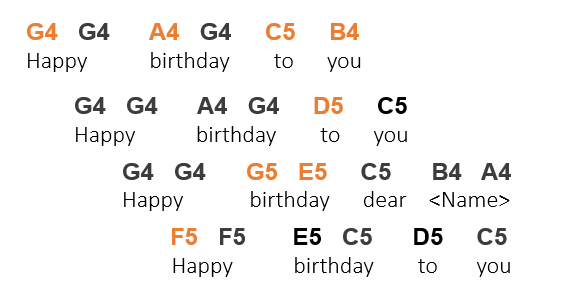

### Create one variable for each unique note (highlighted orange) to store its frequency

G4 = 392;
A4 = 440;


### Call sineSound() function to play the notes

sineSound(G4);

sineSound(G4);

sineSound(A4);

sineSound(G4);


**Helper Functions **(do not edit)

function varargout = sineSound(varargin)

    Fs = 8000; 
    Ts = 1/Fs;
    
if nargin == 1
    freq = round(varargin{1},3);
    time = 0.2 ; 
    amp = 1;
    
elseif nargin == 2
    freq = round(varargin{1},3);
    time = round(varargin{2},3) ; 
    amp = 1;
    
elseif nargin == 3
    freq = round(varargin{1},3);
    time = round(varargin{2},3) ; 
    amp = varargin{3};
   
end

t = 0:Ts:time;
pure_sine = sin(2*pi*freq*t); 
step = 1/(length(t)/2); 
len = 1;
sine_coefficient = [(sin((pi* [0:step:len/2.0]) / (len))) ...
                        ones(1, length([len/2.0:step:len*3/2]) - 2)...
                        abs(sin((pi* [len*3/2:step:len*2.0]) / (len)))]; %#ok<*NBRAK>

env = 0.5*amp.*pure_sine.*sine_coefficient;


if nargout == 1
    varargout{1} = env';
else 
    sound(env, Fs);
end
end

© COPYRIGHT 2024 by The MathWorks®, Inc.